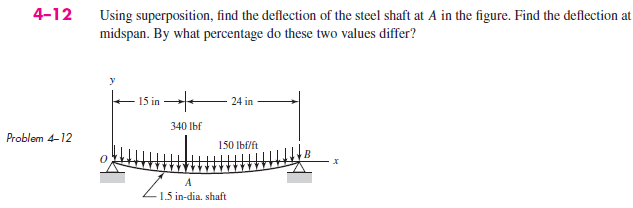

# given

u = symunit;
D = 1.5*u.in;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ro', 0);
b = b.add('applied', 'force', -340*u.lbf, 15*u.in);
b = b.add('reaction', 'force', 'Rb', 39*u.in);
b = b.add('distributed', 'force', rewrite(-150*u.lbf/u.ft, u.lbf/u.in), [0 39]*u.in);
b.L = 39*u.in;

# section properties

b.E = 30e6*u.psi;
b.I = sympi*(D/2)^4/4;

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(65\,x^{3}-9422\,x^{2}\,\mathrm{in}+7968375\,{\mathrm{in}}^{3}\right)}{296156250\,\pi }\,\frac{1}{{\mathrm{in}}^{3}} & \text{ if }x\leq 15\,\mathrm{in}\\ -\frac{\left(x-39\,\mathrm{in}\right)\,\left(13\,x^{3}+37\,x^{2}\,\mathrm{in}-62205\,x\,{\mathrm{in}}^{2}+122400\,{\mathrm{in}}^{3}\right)}{59231250\,\pi }\,\frac{1}{{\mathrm{in}}^{3}} & \text{ if }15\,\mathrm{in}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{260\,x^{3}-28266\,x^{2}\,\mathrm{in}+7968375\,{\mathrm{in}}^{3}}{296156250\,\pi }\,\frac{1}{{\mathrm{in}}^{3}} & \text{ if }x\leq 15\,\mathrm{in}\\ \frac{-52\,x^{3}+1410\,x^{2}\,\mathrm{in}+127296\,x\,{\mathrm{in}}^{2}-2548395\,{\mathrm{in}}^{3}}{59231250\,\pi }\,\frac{1}{{\mathrm{in}}^{3}} & \text{ if }15\,\mathrm{in}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{5\,x\,\left(65\,x-4711\,\mathrm{in}\right)}{52}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }x\leq 15\,\mathrm{in}\\ -\frac{25\,\left(x-39\,\mathrm{in}\right)\,\left(13\,x+272\,\mathrm{in}\right)}{52}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }15\,\mathrm{in}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{5\,\left(130\,x-4711\,\mathrm{in}\right)}{52}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }x\leq 15\,\mathrm{in}\\ -\frac{25\,\left(26\,x-235\,\mathrm{in}\right)}{52}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }15\,\mathrm{in}<x \end{array}\right.$$

w

$$w(x) = -\frac{25}{2}\,\frac{\mathrm{lbf}}{\mathrm{in}}$$

addvar(y);

# reactions

Ro = vpa(r.Ro, 5) %#ok

$$Ro = 452.98\,\mathrm{lbf}$$

Rb = vpa(r.Rb, 5) %#ok

$$Rb = 374.52\,\mathrm{lbf}$$

clear Ro Rb;

# shear and moment diagram

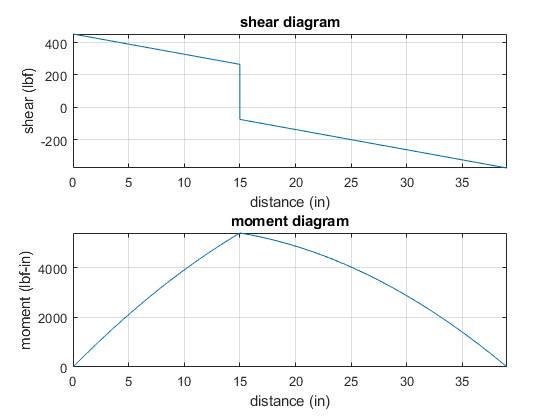

beam.shear_moment(m, v, [0 b.L], {'lbf' 'in'});

# deflections

y_A = y(15*u.in);
y_A_vpa = vpa(y_A, 3) %#ok

$$y\_A\_vpa = -0.0978\,\mathrm{in}$$

y_center = y(b.L/2);
y_center_vpa = vpa(y_center, 4) %#ok

$$y\_center\_vpa = -0.1027\,\mathrm{in}$$

clear y_A_vpa y_center_vpa;